Fa = 100

Fa = 100

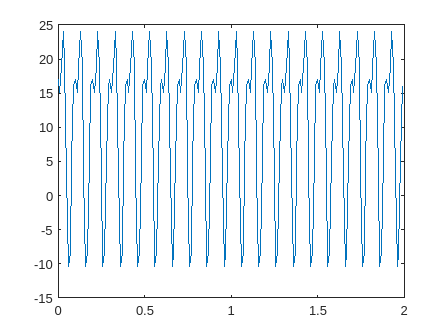


t = 0:1/Fa:2-1/Fa;
x = 10 + 14 *cos(2*pi*10*t-pi/3) + 8*cos(2*pi*20*t+pi/2) ;
N= length(x);
plot(t,x)

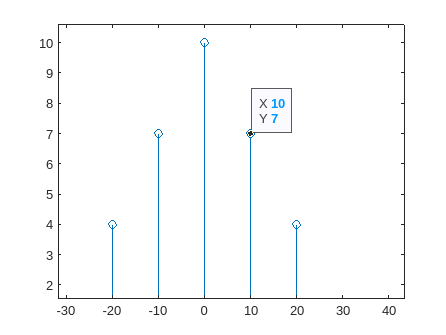

x = fftshift(fft(x));
f=(0:N-1) * (Fa/N);

if rem(N,2) == 0
    f = (-N/2 : N/2 - 1) * (Fa/N);
else
    f=(-(N-1)/2 : (N-1)/2) * (Fa/N)
end

stem(f, abs(x)/N)